# INF250 - CA5 - Deadline May 16th @ 23:59

### Upload your CA5_<Student Name>.mlx submission on Mitt, make sure it is the correct version and double-check (for example by downloading and running it again) to make sure you submitted the right file!

During the fifth round of programming assignments, we focus on a machine learning. To be a bit more specifically: LDA, Decision Trees, and Bayesian Networks.

## Linear Discriminant Analysis (LDA) - 25% of the points:

In the first part of the assignment, we focus on *multi-class linear discriminant analysis*, sometimes also referred to as *multiple discriminant analysis*. LDA corresponds to a *supervised *algorithm meaning that the underlying data is already divided into different classes/categories and we actively use this information. Therefore, we are this time working with the famous *Iris Data Set* (from Fisher, 1936) - UCI Machine Learning Repository ([https://archive.ics.uci.edu/ml/datasets/Iris](https://archive.ics.uci.edu/ml/datasets/Iris)).

Your first task is to import the data, either by downloading the data set from the above webpage or by simply using MATLABs corresponding sample data set.

**Hint: ***An overview of MATLABs sample data sets is available under *[https://se.mathworks.com/help/stats/sample-data-sets.html](https://se.mathworks.com/help/stats/sample-data-sets.html).

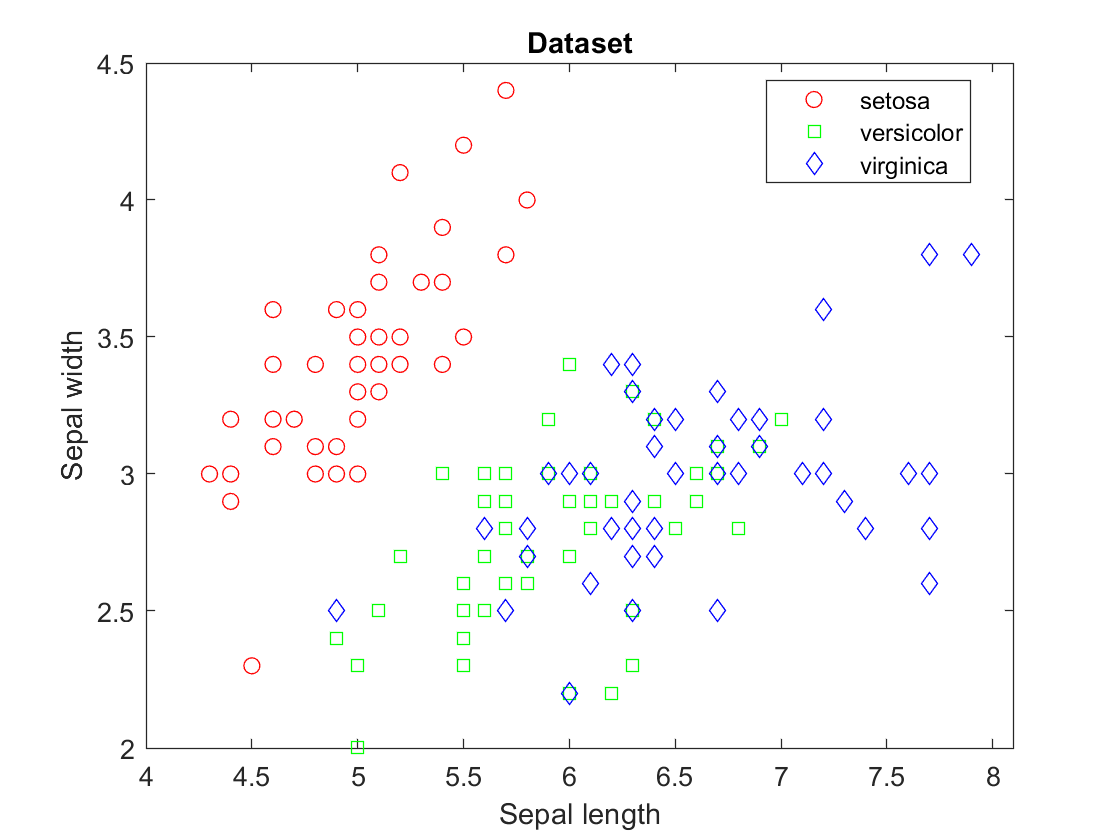

clc; clear; close all;

load fisheriris.mat

figure();
gscatter(meas(:,1), meas(:,2), species,'rgb','osd');
xlabel('Sepal length');
ylabel('Sepal width');
title("Dataset")

To understand the data better, your next task is to create a visualization consisting of four sub-plots. Each sub-plot should thereby be a histogram of one of the features provided in the data, i.e., the *sepal length*, the *sepal width*, the *petal length*, and the* petal width*. As always, make sure that each sub-plot has an x-axis and y-axis label, and a legend. In addition, play around with face color and face alpha to maximize the expressiveness of your information visualization. Think about how many bins you want to use, how many bins would be too little, how many bins would be too many?

**Hint: ***The MATLAB 'subplot' functionality might be useful to create visualizations consisting of several sub-plots.*

**Hint: ***The MATLAB 'histogram' functionality might be useful to create histograms. Additionally, make sure to check out the 'edges', 'FaceColor', and 'FaceAlpha' parameters.*

**Hint: ***The MATLAB 'hold on' and 'hold off' functionalities might be useful to create histograms of multiple categories (e.g., setosa, vericolor, and virginica) by using several function calls on the same plot.*

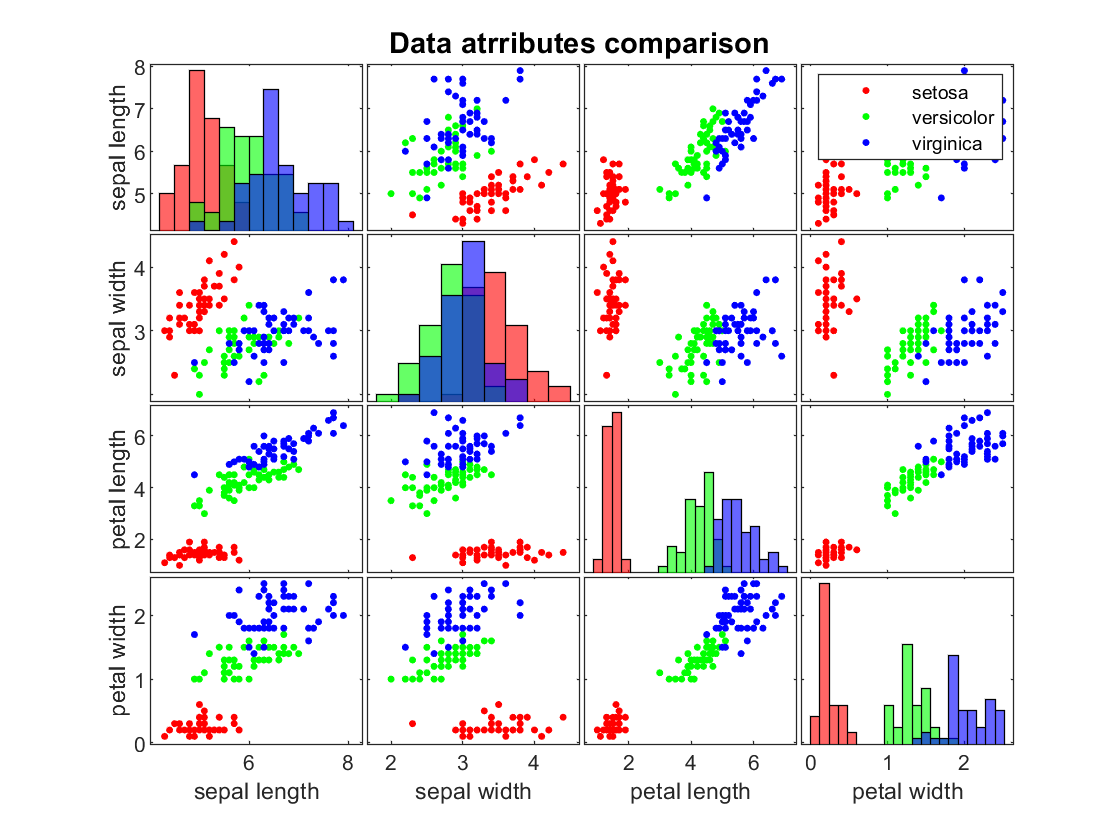

figure();
l = {'sepal length' 'sepal width' 'petal length' 'petal width'};
gplotmatrix(meas,[],species,"rgb",[],[],[],"grpbars", l)
title("Data atrributes comparison")

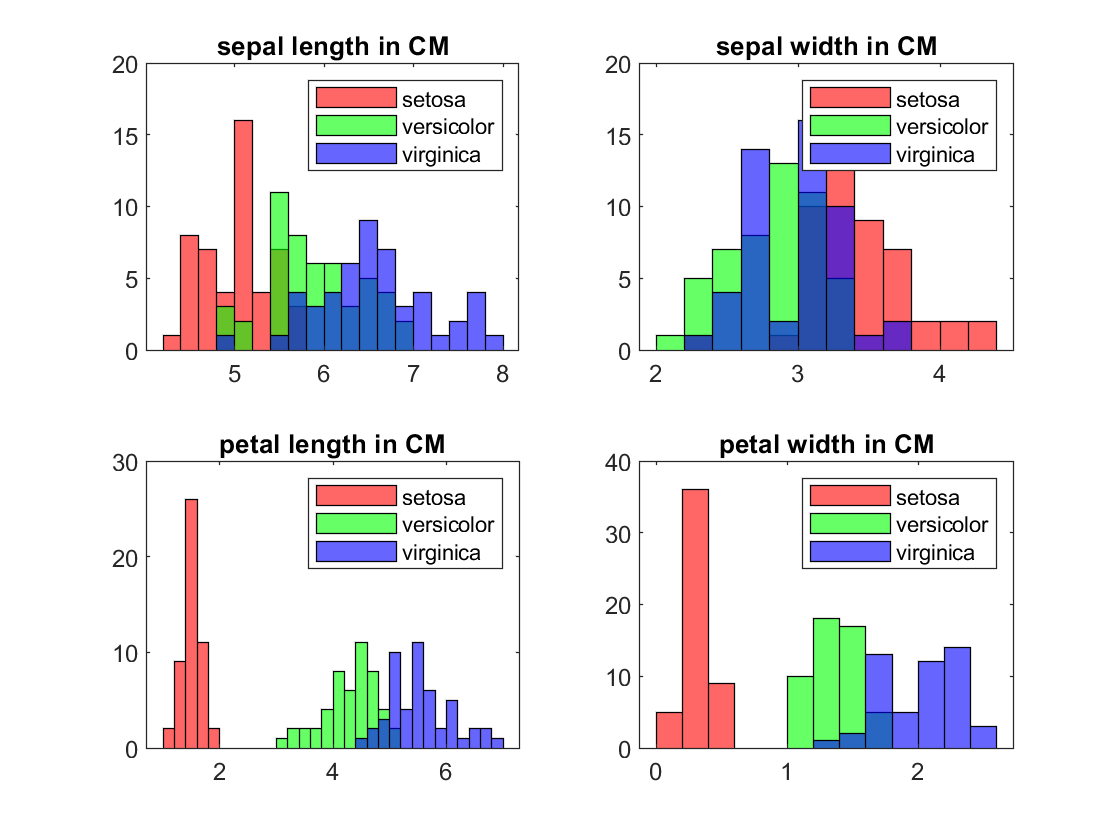



figure();
c = ["r", "g", "b"];
specieslabels = [species(1) species(51) species(150)];
measlabels = ["sepal length" "sepal width" "petal length" "petal width"];
for i = 1:4
    subplot(2,2,i)
    
    for k = 1:1:3
        histogram(meas((k-1) * 50 +1: k*50, i), "BinWidth",0.20, "FaceColor",c(k))
        hold on
    end
    legend(specieslabels)
    title(measlabels(i) + " in CM")
    hold off
end

Generally, LDA assumes normally distributed data, therefore, your task is to next check whether the individual categories are normally distributed. Note, however, that discriminant analysis is relatively robust to "slight" violations of this assumption, according to Lachenbruch, P. A. (1975) - *Discriminant analysis*. 

Use *Jarque-Bera test* to test if the data comes from a normal distribution with an unknown mean and variance at a 5% significance level. What does the test reveal about the categories within data?

**Hint: ***The MATLAB 'jbtest' functionality might be useful to perform a Jarque-Bera test.*

% Checking all category permutations. Setose petal width/height, sepal
% width/height ...

for i = 1:4    
    for k = 1:1:3
        data = meas((k-1)*50 + 1: k*50, i);
        jbtest(data)
    end
end

ans = 0

ans = 0

ans = 0

ans = 0

ans = 0

ans = 0

ans = 0

ans = 0

ans = 0

ans = 1

ans = 0

ans = 0


% One of the tests fails, the setosa petal width. We can explain this
% by looking at the earlier plots, where the histogram is very pointy...


After exploring the histograms, you chose to use *petal length* and *petal width* as basis for a linear classifier. Create a new figure containing only a scatter plot using *petal length* as x-axis and *petal width* as y-axis. Use the same colors as you already used in your histograms to color different classes and use varying marker symbols. Then, plot two lines - resulting from MATLABs linear discriminant analysis classifier - that can be used to separate all three classes accordingly. What do you observe? Do all data points get classified correctly? If not, how many are wrongly classified? 

**Hint: ***The MATLAB 'gscatter' functionality might be useful to create a scatter plot.*

**Hint: ***The MATLAB 'fitcdiscr' functionality might be useful to create a linear discriminant analysis classifier.*

**Hint: ***The MATLAB 'fimplicit' functionality might be useful to plot an implicit function.*

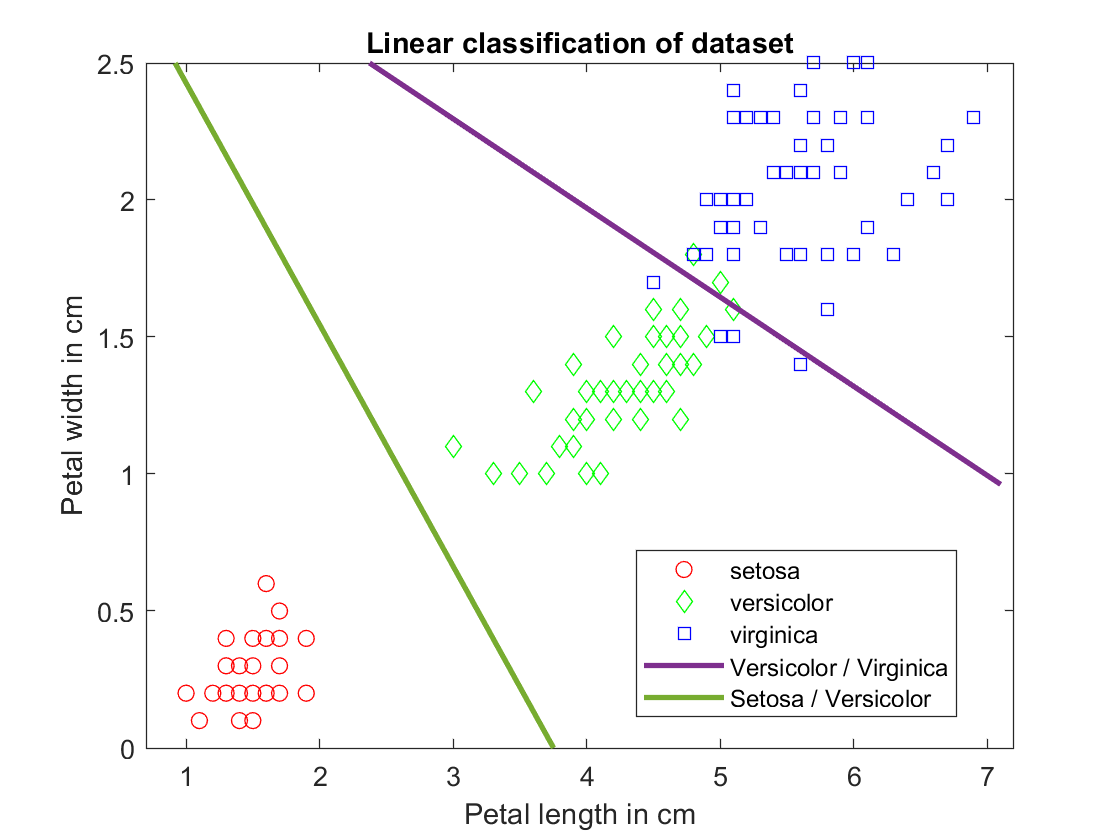

Mdl = fitcdiscr(meas(:,3:4), species);
K1 = Mdl.Coeffs(2,3).Const;
L1 = Mdl.Coeffs(2,3).Linear;
f1 = @(x1,x2) K1 + L1(1)*x1 + L1(2)*x2;

K2 = Mdl.Coeffs(1,2).Const;
L2 = Mdl.Coeffs(1,2).Linear;
f2 = @(x1,x2) K2 + L2(1)*x1 + L2(2)*x2;

figure();
gscatter(meas(:,3), meas(:,4), species, "rgb", "ods")
hold on
h2 = fimplicit(f1,[.9 7.1 0 2.5]);
h2.DisplayName = "Versicolor / Virginica";
h2.LineWidth = 2;

h3 = fimplicit(f2,[.9 7.1 0 2.5]);
h3.DisplayName = "Setosa / Versicolor";
h3.LineWidth = 2;

xlabel("Petal length in cm")
ylabel("Petal width in cm")
hold off
title("Linear classification of dataset")


% Not all datapoints are classidied correctly, we se the split between
% versicolor and virginica is not clear and there are wrong points
% classified on each side of the linear classification. There are 4
% virginica datapoints classified wrong and 2 versicolor points.


%https://se.mathworks.com/help/stats/create-and-visualize-discriminant-analysis-classifier.html
%https://se.mathworks.com/help/stats/visualize-decision-surfaces-for-different-classifiers.html
%https://se.mathworks.com/help/stats/classification-example.html

## LDA Summary - mandatory to receive points:

Use the box below to tell us what you learned when implementing LDA. 

**What is *****petal***** or *****sepal***** width/length? **

Sepal is part of the plant that is under the flower, whilst petal is the flowers themselves

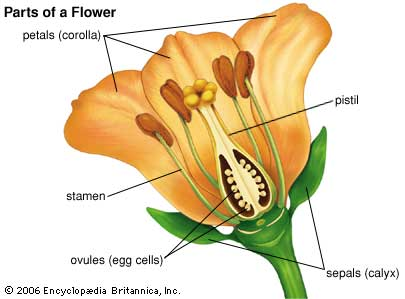

**How many bins did you use when creating the individual histograms (how many bins would be too much/ too little)? **

When testing i found that 0.2 as binwidth ws appropriate. This means that there are 5 bins in each complete integer step. Too many bind would be smaller binwidths, and to few bins would be higher binwidth.

**By looking at all four histograms, can you tell which features are likely better suited to separate between the three flower classes, i.e., sepal VS petal properties or length VS width properties? **

The petal length and width are clearly the features which are most likely to seperate between the three species. We can see this on the graphs since the bins are more clearly seperated.

**What did Jarque-Bera test reveal about the data, are all categories normal distributed? **

The Jarque-Bera test reveals that all attributes for all species are normal distributed , except in one case for the petal width for setosa.

**What other tests could you perform to find out whether a variable is normal distributed? **

A boxplot shows visually whether the data is normal distubuted. There are many statistical methods to see if data is normally distrubuted sush as Shapiro Wilk test, Lilliefors test and Kolomogorov Smirnov test

**What did you observe when performing your linear discriminant analysis classification? **

I observed that for the given data set we could pretty clearly classify data linearly. I imagine for more sparse groupings and generally larger sets with more species and attributes a linear approximation would not be sufficient. But it seems to do the job in our case.

**Were sample points misclassified? If so, which classes could be nicely separated and which not?**

Some sample points were misclassified. Setosa is clearly seperated from the others when it comes to petal width and length, but versicolor ans virginica is more similar. This causes the few misclassifications of wide and long petal measurments of versicolor, and narrow and short petal measuments of virginica.

## Decision Trees - 25% of the points:

In the second part of the assignment, we focus on decision trees, here also used for classification. We, therefore, continue working with the *Iris Data Set* (from Fisher, 1936) - UCI Machine Learning Repository ([https://archive.ics.uci.edu/ml/datasets/Iris](https://archive.ics.uci.edu/ml/datasets/Iris)). If you have not loaded the data, for example, because you skipped the LDA exercise, make sure you load it now, otherwise it is already in your workspace :)

**Hint: ***An overview of MATLABs sample data sets is available under *[https://se.mathworks.com/help/stats/sample-data-sets.html.](https://se.mathworks.com/help/stats/sample-data-sets.html.)

Then, create a binary decision tree and visualize the resulting tree as:

- text description, and

- graphic description.

**Hint: ***The MATLAB 'fitctree' functionality might be useful to fit a binary decision tree for multiclass classification*

**Hint: ***The MATLAB 'view' functionality and its parameters might be useful to visualize the decision tree as text or graph.*

t = fitctree(meas, species, 'PredictorNames',{'Sepal length', 'Sepal width', 'Petal length', 'Petal width'});
view(t);

Decision tree for classification
1  if Petal length<2.45 then node 2 elseif Petal length>=2.45 then node 3 else setosa
2  class = setosa
3  if Petal width<1.75 then node 4 elseif Petal width>=1.75 then node 5 else versicolor
4  if Petal length<4.95 then node 6 elseif Petal length>=4.95 then node 7 else versicolor
5  class = virginica
6  if Petal width<1.65 then node 8 elseif Petal width>=1.65 then node 9 else versicolor
7  class = virginica
8  class = versicolor
9  class = virginica



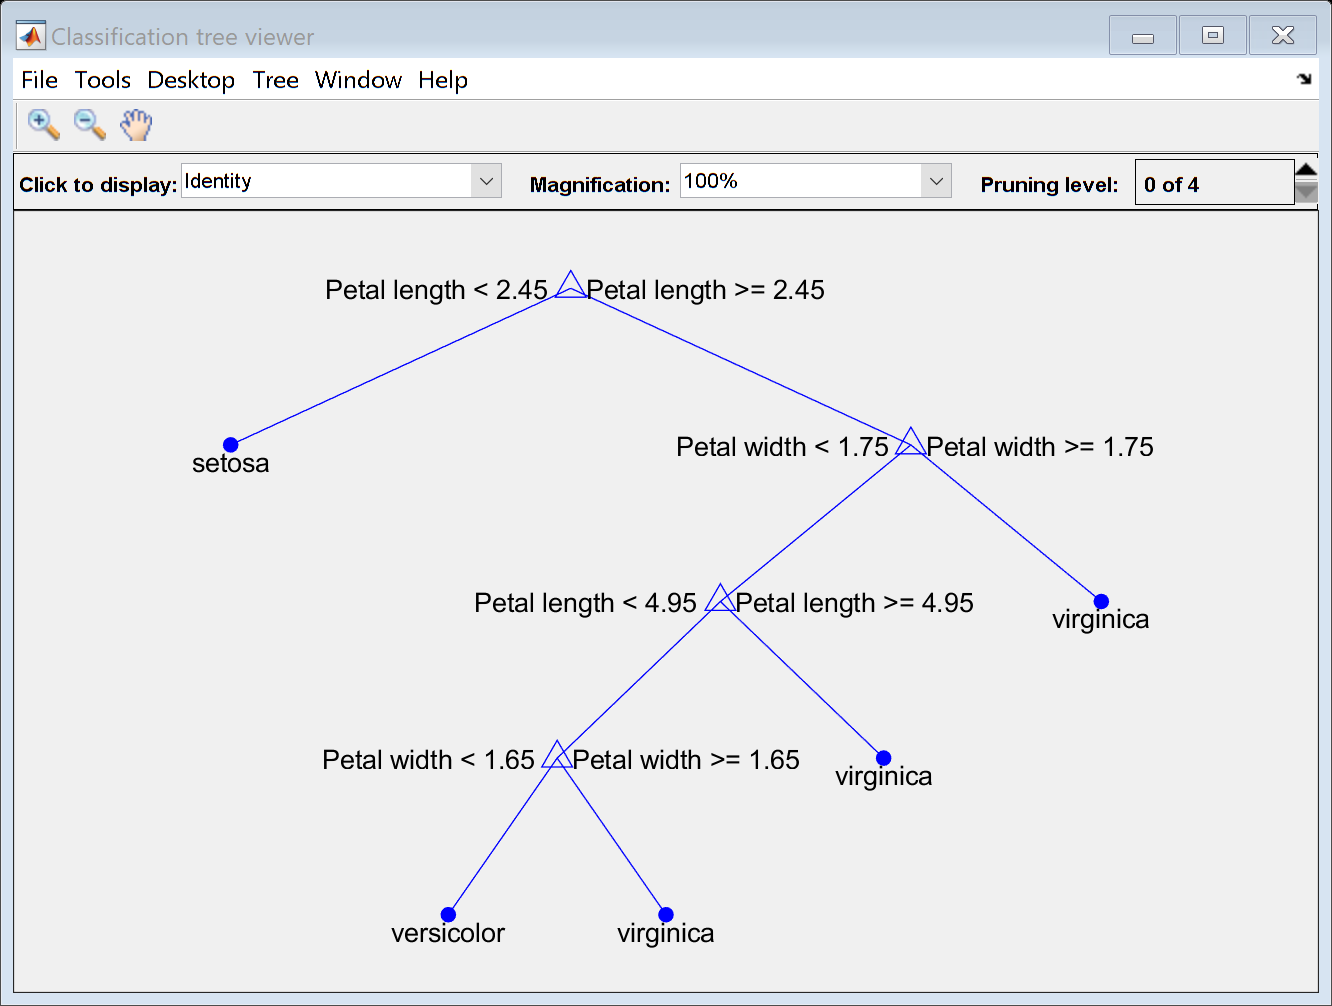

view(t,'Mode','graph');

There are different techniques of how to evaluate/predict the accuracy of a decision tree. We focus on one possibility namely *cross-validation*. Particularly, we focus on *k-fold* and *leave-one-out cross-validation* (*LOOCV*). Your task is to first calculate the predicted accuracy/classification loss for the previously generated decision tree using MATLABs *cross-validation* functionality for k=5.

**Hint: ***The MATLAB 'crossval' functionality might be useful for k-fold cross-validation. Check the necessary parameters for 5-fold cross-validation.*

**Hint: ***The MATLAB 'cvloss' functionality might alternatively be useful for cross-validation. Check the parameters for 5-fold cross validation.*

rng('default')
cval = crossval(t, 'KFold', 5);
L = kfoldLoss(cval);
disp("K-fold loss " + L)

K-fold loss 0.06


disp('About 8 miscalculations (0.06 / 150)')

About 8 miscalculations (0.06 / 150)


Second, you will *manually* calculate LOOCV. Note that this time, you are not allowed to estimate the LOOCV using a MATLAB function (for example 'crossval', 'cvloss', and so on) but instead, you should loop over your data set, create a decision tree by leaving a single data item out and then, use exactly this data item as input for your prediction. Was the left-out item correctly classified?

LOOCV: [https://en.wikipedia.org/wiki/Cross-validation_(statistics)#Leave-one-out_cross-validation](https://en.wikipedia.org/wiki/Cross-validation_(statistics)#Leave-one-out_cross-validation)

meas_size = size(meas);
species_size = size(species);
loss = 0;

for i = 1:1:150
    temp = meas;
    temp(i,:) = [];
        
    temp_s = species;
    temp_s(i) = [];
    
    t = fitctree(temp, temp_s);

    if ~strcmp(cell2mat(t.predict(meas(i,:))), cell2mat(species(i)))
        loss = loss + 1;
    end

end

LOOCV = loss / 150

LOOCV = 0.0467

## Decision Tree Summary - mandatory to receive points:

Use the box below to tell us what you learned when implementing the decision tree assignment. 

**Is there a class that is especially easy to classify? **

As we also saw in the previous task, Setosa is easy to classify comapreds to the two others.

**Given the computational effort of leave-one out cross-validation, would you use it on rather large data sets (consisting of thousands or millions of entries) or smaller data sets? **

The computational effort is far to large for using this cross-validation on large datasets. One would have to fit a model N times based on the size of the data, and the time of fitting a model already grows by N.

**What happens if k is equal to the size of the data set?**

This would be the same as leave-one-out since the dataset is split into N traingsets, which is the same procedure as we did.

## Bayesian Networks - 50% of the points:

During the last part of this assignment, we focus on the *Bayes Net Toolbox for Matlab *provided by the University of Utah - School of Computing ([https://www.cs.utah.edu/~tch/notes/matlab/bnt/docs/bnt_pre_sf.html](https://www.cs.utah.edu/~tch/notes/matlab/bnt/docs/bnt_pre_sf.html)). Your first task is, therefore, to download and install the toolbox.

GitHub Repository: [https://github.com/bayesnet/bnt](https://github.com/bayesnet/bnt)

HowToInstall (Tested on MATLAB R2020a): [https://github.com/bayesnet/bnt/wiki/HowToInstall](https://github.com/bayesnet/bnt/wiki/HowToInstall)

**Hint: ***For your submission, you can assume that the Bayes Net Toolbox for Matlab is already installed on the machine that is used to correct your assignment. There is, therefore, no need to include any additional files of functions.*

To get familiar with the toolkit, your next task is to reimplement the Bayesian network used during lecture (INF250-VisIntro-L7a-ML1--print.pdf), also shown in the figure below:

                                                              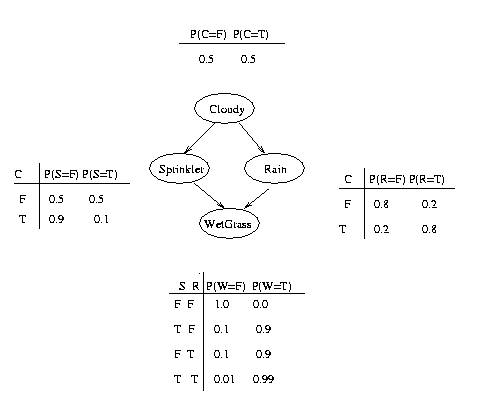

**Hint: ***Bayes Net Toolbox for Matlab provides a usage example of exactly this example network (*[https://www.cs.utah.edu/~tch/notes/matlab/bnt/docs/usage.html](https://www.cs.utah.edu/~tch/notes/matlab/bnt/docs/usage.html))

clc; clear; close all;

N = 4; 
dag = false(N,N);
C = 1; S = 2; R = 3; W = 4;
dag(C,[R S]) = true;
dag(R,W) = true;
dag(S,W) = true;

discrete_nodes = 1:N;
node_sizes = 2*ones(1,N); 

bnet = mk_bnet(dag, node_sizes, 'names', {'cloudy','S','R','W'}, 'discrete', 1:4);

bnet.CPD{C} = tabular_CPD(bnet, C, [0.5 0.5]);
bnet.CPD{R} = tabular_CPD(bnet, R, [0.8 0.2 0.2 0.8]);
bnet.CPD{S} = tabular_CPD(bnet, S, [0.5 0.9 0.5 0.1]);
bnet.CPD{W} = tabular_CPD(bnet, W, [1 0.1 0.1 0.01 0 0.9 0.9 0.99]);

To evaluate whether your implementation is correct, calculate:

- Probability that the sprinkler was on given that the grass is wet.

- Probability that the sprinkler was on given that the grass is wet, and it is raining.

**Hint: ***Again,* *Bayes Net Toolbox for Matlab provides both calculations as their usage examples (*[https://www.cs.utah.edu/~tch/notes/matlab/bnt/docs/usage.html](https://www.cs.utah.edu/~tch/notes/matlab/bnt/docs/usage.html))

engine = jtree_inf_engine(bnet);

% 1.) Probability that the sprinkler was on given that the grass is wet.
evidence = cell(1,N);
evidence{W} = 2;
[engine, loglik] = enter_evidence(engine, evidence);
marg = marginal_nodes(engine, S);

p1 = 0.4298

p1 = marg.T(2)

% 2.) Probability that the sprinkler was on given that the grass is wet and it is raining.
evidence{R} = 2;
[engine, loglik] = enter_evidence(engine, evidence);
marg = marginal_nodes(engine, S);

p2 = 0.1945

p2 = marg.T(2)

As last part of the Bayesian networks, it is your turn to be creative again. Come up with a scenario that requires or could profit from such a Bayesian network. Start by taking a sheet of paper and sketching a network that consists of at least 6 nodes and has tables for all probabilities. Embed a photo or scan of that sketch, similar to how it was done in the last assignments (pressing the "INSERT" tab in the MATLAB menu allows you to embed "Images"), before handing it in so that we see the network you wanted to create. Then, implement the scenario and come up with at least two interesting questions, similar to "the probability that the sprinkler was on given that the grass is wet (and it was raining)" from above. 

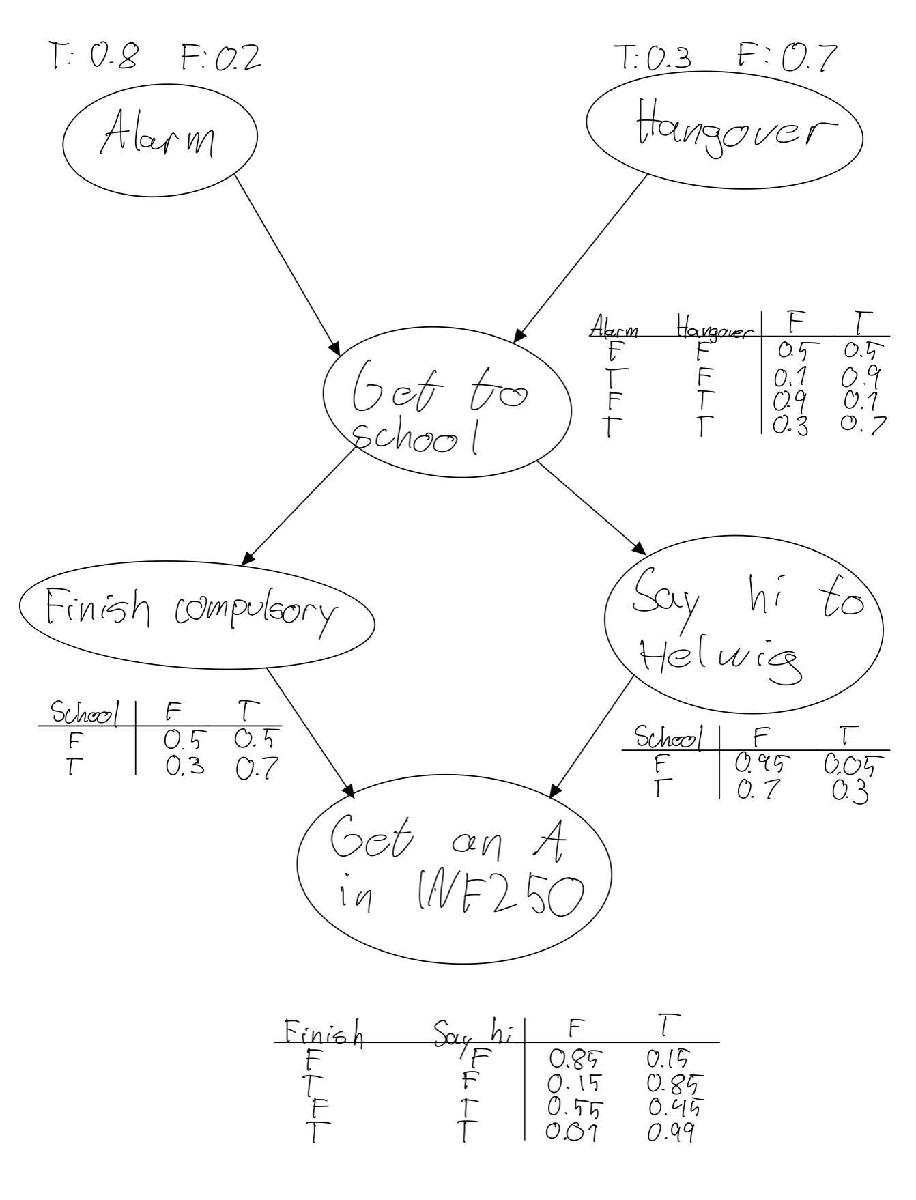

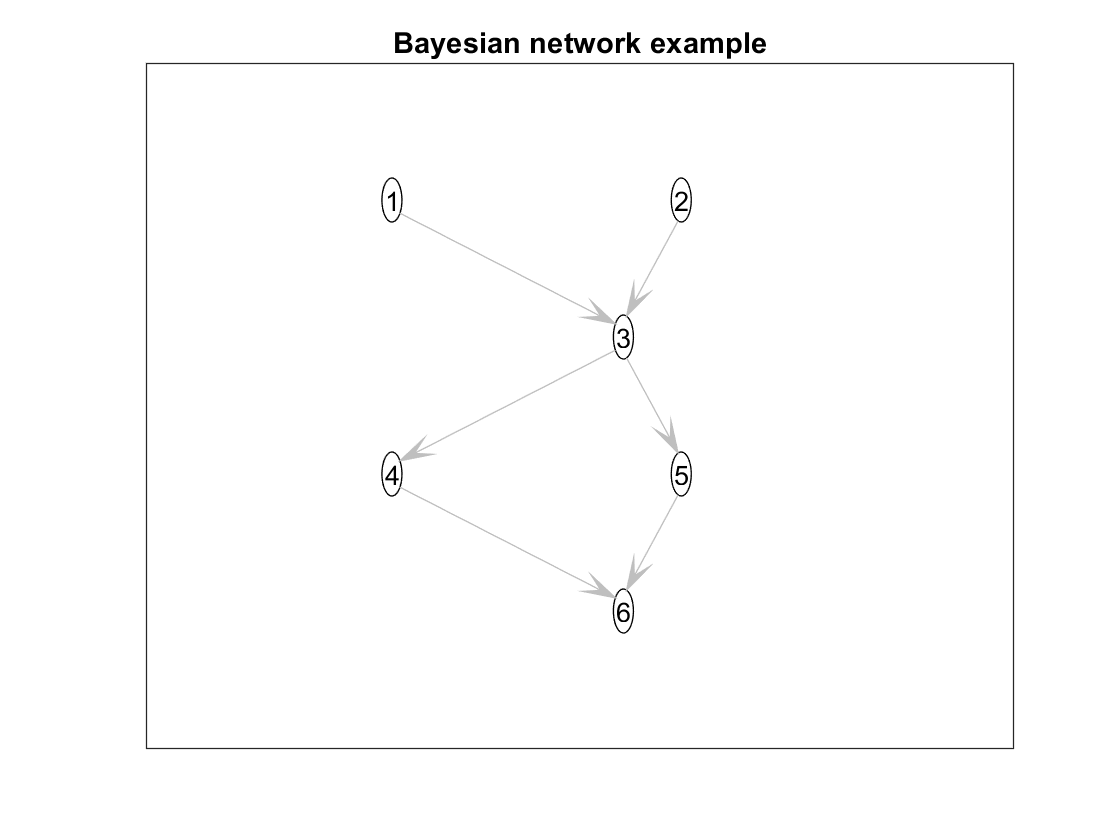

clc; clear; close all;


N = 6; 
dag = false(N,N);
A = 1; B = 2; C = 3; D = 4; E = 5; F= 6;
dag(A,C) = true;
dag(B,C) = true;
dag(C,[D E]) = true;
dag(D,F) = true;
dag(E,F) = true;

discrete_nodes = 1:N;
node_sizes = 2*ones(1,N); 

my_bnet = mk_bnet(dag, node_sizes, 'names', {'Alarm','Hangover','Get to school','Finish compulsory','Say hi to Helwig','Get an A in INF250'}, 'discrete', 1:6);

my_bnet.CPD{A} = tabular_CPD(my_bnet, A, [0.2, 0.8]);
my_bnet.CPD{B} = tabular_CPD(my_bnet, B, [0.7, 0.3]);
my_bnet.CPD{C} = tabular_CPD(my_bnet, C, [0.5, 0.1, 0.9, 0.3, 0.5, 0.9, 0.1, 0.7]);
my_bnet.CPD{D} = tabular_CPD(my_bnet, D, [0.5, 0.3, 0.5, 0.7]);
my_bnet.CPD{E} = tabular_CPD(my_bnet, E, [0.95, 0.7, 0.05, 0.3]);
my_bnet.CPD{F} = tabular_CPD(my_bnet, F, [0.85, 0.15, 0.55, 0.01, 0.15, 0.85, 0.45, 0.99]);

figure()
draw_graph(my_bnet.dag);
title("Bayesian network example")




engine = jtree_inf_engine(my_bnet);
disp("Probability that you finish compulsory given that you are hangover.")

Probability that you finish compulsory given that you are hangover.


evidence = cell(1,N);
evidence{B} = 2;
[engine, loglik] = enter_evidence(engine, evidence);
marg = marginal_nodes(engine, D);
p1 = marg.T(2)

p1 = 0.6160


disp("Probability that you get an A given that you are hangover and you say hi to Helwig.")

Probability that you get an A given that you are hangover and you say hi to Helwig.


evidence{E} = 2;
[engine, loglik] = enter_evidence(engine, evidence);
marg = marginal_nodes(engine, F);
p2 = marg.T(2)

p2 = 0.8164

## Summary - mandatory to receive points:

Use the box below to tell us what you learned during this programming assignment for Bayesian networks. 

**What were the interesting questions you tried to answer? **

Well the question was not really that interesting, but i tried to simulate a couple of events that would affect your ability to get an A in INF250. And then jokingly included saying hi to Helwing and being hangover.

**What insights did you gain? **

My insights are more on the technical side, where i have learned a lot about the bayesian network structure. I understand it is a very powerfull tool and the reasearch area is really interesting. When it comes to getting an A in INF250 you should really wake up by alarm, get to school, finish this compulsory and say hi to Helwig in the elevator.

**What insight could others gain that use this network in future? **

Future student of INF250 could study the network and understand what the different values mean, and in the future expand this network to make a complete network of all the possible outcomess when taking INF250.

**Where would your Bayesian network be used: at university, at work, in the hospital, ... or somewhere completely different?**

It would be used by students trying to excell in their academic field, or just for jokes.